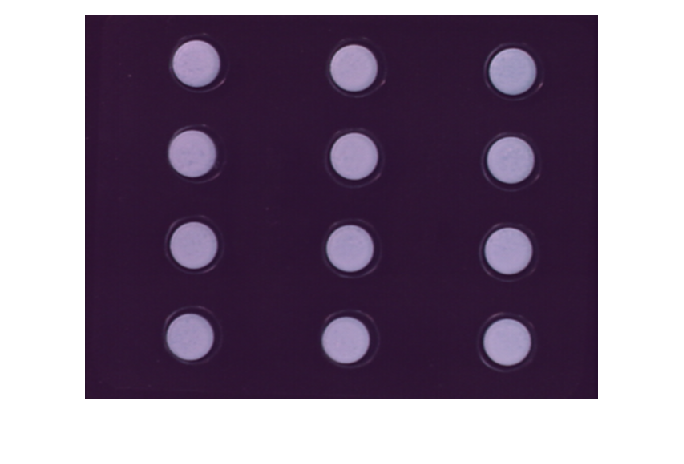

B1 = imread('Blispac1.tif');
imshow(B1)


B2 = imread('Blispac2.tif');
%imshow(B2)


1. Obtenir la imatge diferència entre el patró i la imatge Blispac2, i comprovar si la falta d'aliniament entre les imatges pot portar problemes en el control de qualitat.

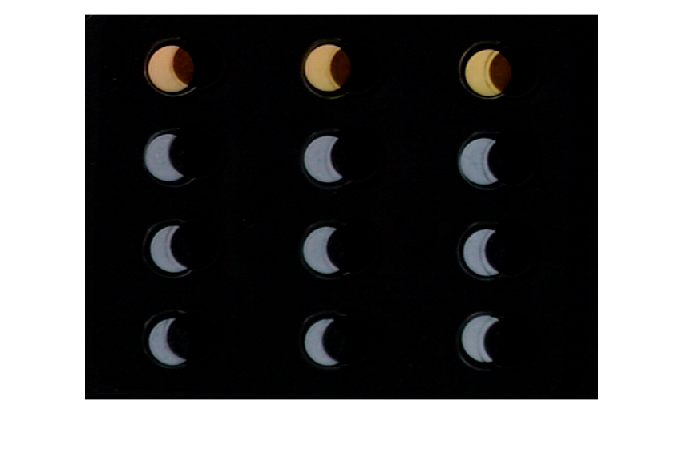

diferencia = B2 - B1;
imshow(diferencia)

2. Obtenir la matriu de tranformació afí (T) que permeti alinear les dues imatges. Els valors de la matriu T s'hauran d'obtenir resolent les equacions pertinents, a partir de les coordenades de les pastilles en les imatges (podeu obtenir les coordenades de forma manual).

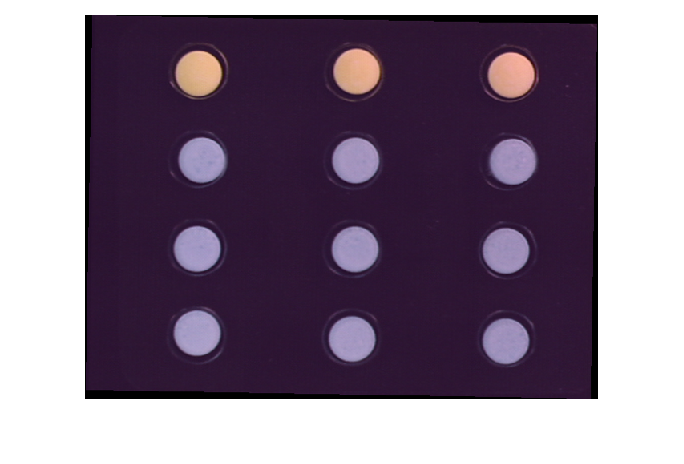

angle = 179;
A = [  cosd(angle)  -sind(angle)  0; 
       -sind(angle)  -cosd(angle)  0;
       0  0  1];
t_aff = affinetform2d(A);

I_affine = imwarp(B2,t_aff);
I_affine = imresize(I_affine, [480 640]);

imshow(I_affine)

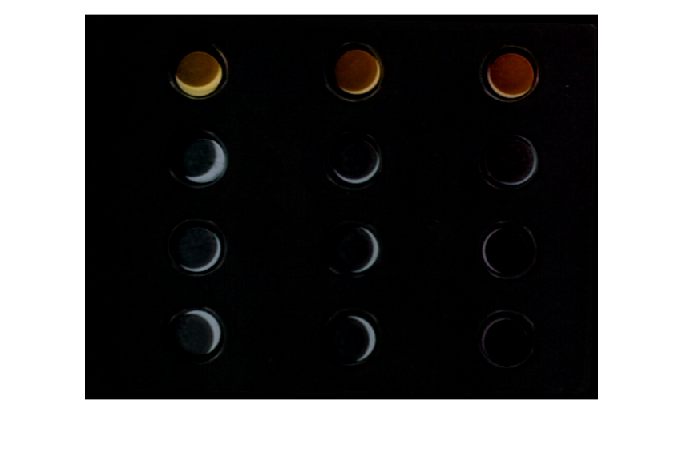


D = I_affine - B1;

imshow(D)